# Lista 2

**Zad. 1.**  Utwórz wektor `t` o 10 elementach 1,2,3...10. 

t = [1:10]

t =      1     2     3     4     5     6     7     8     9    10


Oblicz:


$$x = t\sin(t)$$


x = t.*sin(t)

x =     0.8415    1.8186    0.4234   -3.0272   -4.7946   -1.6765    4.5989    7.9149    3.7091   -5.4402



$$y = \frac{t-1}{t+1}$$


y = (t-1)./(t+1)

y =          0    0.3333    0.5000    0.6000    0.6667    0.7143    0.7500    0.7778    0.8000    0.8182



$$z = \frac{\sin(t^2)}{t^2}$$


z = (sin(t.^2))./(t.^2)

z =     0.8415   -0.1892    0.0458   -0.0180   -0.0053   -0.0275   -0.0195    0.0144   -0.0078   -0.0051


**Zad.2.** Równanie prostej ma postać $y=m\;x+c$, gdzie wartosći $m$ i $c$ są stałe. Oblicz współrzędne$y$ przy nachyleniu $m=0\ldotp 5$ oraz $c=-2$ dla następujących współrzędnych $x$:

`x = 0, 1.5, 3, 4, 5, 7, 9, 10.`

m = 0.5;
c = -2;
x = [0 1.5 3 4 5 6 9 10]

x =          0    1.5000    3.0000    4.0000    5.0000    6.0000    9.0000   10.0000


y = m.*x + c;

Proszę narysować otrzymane wyniki poleceniem: `plot(x,y)`

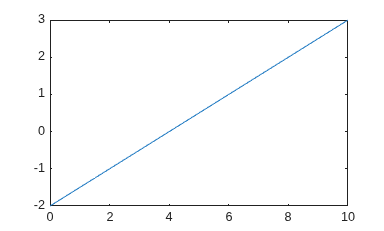

plot(x,y)

**Zad.3** Utwórz tablicę $A\left(10,10\right)$ zawierającą losowe liczby całkowite z przedziału $\left(0,50\right)$. 

A = round(rand(10).*50)

A =     48    38    36    36    44    18     9     9     0    30
    27     7    10    43     6     3    12    31    40    40
    13    18    11     6    18    35     3    29    25    49
    29    20    49     2    12    50    30    38    27    44
    46    44    30    30    28     8    39     8    44    11
    45     1    15    30    31     6    26    18    36     2
    24    42    48    26    15    46     1     7    33    23
    22    14    45     0    40    24    50    43     9     1
    16    13    10    34    40    43    25    17    28    24
     3    24     0    47    39    40    17    14    48    48


Napisz jedną instrukcję, która przekształca tablicę $A$ w następujący sposób:

- usuwa trzeci wiersz

A(3,:) = []

A =     19    49    45    10    27    37    30    41    19    24
    16    25    14    22    28    47    22    15    22    13
    36     3    30    44    19    12    13    44    15     9
    21     7    24    31     4    13     5    35    12    43
     5    45    18    10    23    38    23    12    47     2
    37    23    33    26     2    50    32    38    43    17
    32    28    47     3    37    18     7    15    20    37
     4    25    31    43     2    38    23    14    24    32
     6     3    14    22    48     6    33     0    28     8


- usuwa wiersze o parzstych numerach

A([2:2:end],:) = []

A =     19    49    45    10    27    37    30    41    19    24
    36     3    30    44    19    12    13    44    15     9
     5    45    18    10    23    38    23    12    47     2
    32    28    47     3    37    18     7    15    20    37
     6     3    14    22    48     6    33     0    28     8


- zastępuje trzeci wiersz wierszem postaci: 1, 2, 3, ...

A(3,:) = [1:10]'

A =     19    49    45    10    27    37    30    41    19    24
    36     3    30    44    19    12    13    44    15     9
     1     2     3     4     5     6     7     8     9    10
    32    28    47     3    37    18     7    15    20    37
     6     3    14    22    48     6    33     0    28     8


- dopisuje na dole tablicy wiersz samych jedynek

A(end,:) = ones(10,1)'

A =     19    49    45    10    27    37    30    41    19    24
    36     3    30    44    19    12    13    44    15     9
     1     2     3     4     5     6     7     8     9    10
    32    28    47     3    37    18     7    15    20    37
     1     1     1     1     1     1     1     1     1     1


- zamienia miejscami wiersz 1 i 4

A([1 3],:) = A([3 1],:)

A =     32    28    47     3    37    18     7    15    20    37
    36     3    30    44    19    12    13    44    15     9
     1     2     3     4     5     6     7     8     9    10
    19    49    45    10    27    37    30    41    19    24
     1     1     1     1     1     1     1     1     1     1


- zamienia miejscami kolumny drugą i ostatnią

A(:, [2 end]) = A(:, [end 2])

A =     48    38    36    36    44    18     9     9     0    30
    27     7    10    43     6     3    12    31    40    40
    13    18    11     6    18    35     3    29    25    49
    29    20    49     2    12    50    30    38    27    44
    46    44    30    30    28     8    39     8    44    11
    45     1    15    30    31     6    26    18    36     2
    24    42    48    26    15    46     1     7    33    23
    22    14    45     0    40    24    50    43     9     1
    16    13    10    34    40    43    25    17    28    24
     3    24     0    47    39    40    17    14    48    48


**Zad. 4**. Utwórz tablicę $3\times 4$ z losowymi wartościami. Przekształć ją funkcją `reshape()` na wszystkie możliwe sposoby.

B = rand(3,4)

B =     0.5971    0.3884    0.8620    0.2361
    0.2978    0.8177    0.0838    0.3178
    0.1250    0.9812    0.3377    0.9844



reshape(B,[[1 2 4 6] [12 6 3 2 1]])

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

reshape(B,[2 6])
reshape(B,[4 3])
reshape(B,[6 2])
reshape(B,[12 1])

**Zad. 5.** Utwórz tablicę $3\times 5$ z losowymi wartościami z zakresu -5 do 5 i przechowaj ją w jakiejś zmiennej. Utwórz inną zmienną, w której będą warstości bezwględne elementów pierwszej tablicy.

C = round(rand(3,5)*10-5)

C =     -3    -4     3     0     0
    -3     0     3     2    -2
    -3     2     2     5     3


D = abs(C)

D =      3     4     3     0     0
     3     0     3     2     2
     3     2     2     5     3
